balModes = ESPConst.BALANCE_MODES;
for i=(1:length(balModes))
    mode = balModes(i);
    preprocessDatasets(true, mode);
end

datasets = dir(ESPConst.PATH_DATASET_PREPROCESSED + "*" + ESPConst.EXTENSION_DATA);
for i=1:length(datasets)
    n = datasets(i).name;
    if ~ contains(n, "-" + ESPConst.BALANCE_MODE_LARGEST_SUM)
        continue;
    end
    path = ESPConst.PATH_DATASET_PREPROCESSED + n;
    [t, v] = prepareInput(path, ESPConst.RATIO_TRAIN, ESPConst.RATIO_VAL);
    bayesOptimizationLSTM(t, v, n);
end

datasets = dir(ESPConst.PATH_DATASET_PREPROCESSED + "*" + ESPConst.EXTENSION_DATA);
for i=1:length(datasets)
    n = datasets(i).name;
    if ~ contains(n, "-" + ESPConst.BALANCE_MODE_LARGEST_SUM)
        continue;
    end
    path = ESPConst.PATH_DATASET_PREPROCESSED + n;
    trainInput = load(path).data;
    bayesOptimizationAE(trainInput, n);
end

Training CNN for 112502-2.mat...

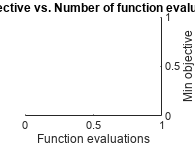

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |       33.40% |       47.04% |       1.3956 |       1.3130 |          0.1094 |
|      25 |          50 |       00:00:08 |       36.68% |              |   1.1177e+19 |              |          0.1094 |
|      36 |          71 |       00:00:10 |        5.02% |       50.16% |   3.6774e+27 |   3.3624e+27 |          0.1094 |
|      50 |         100 |       00:00:14 |        3.28% |              |          NaN |              |          0.

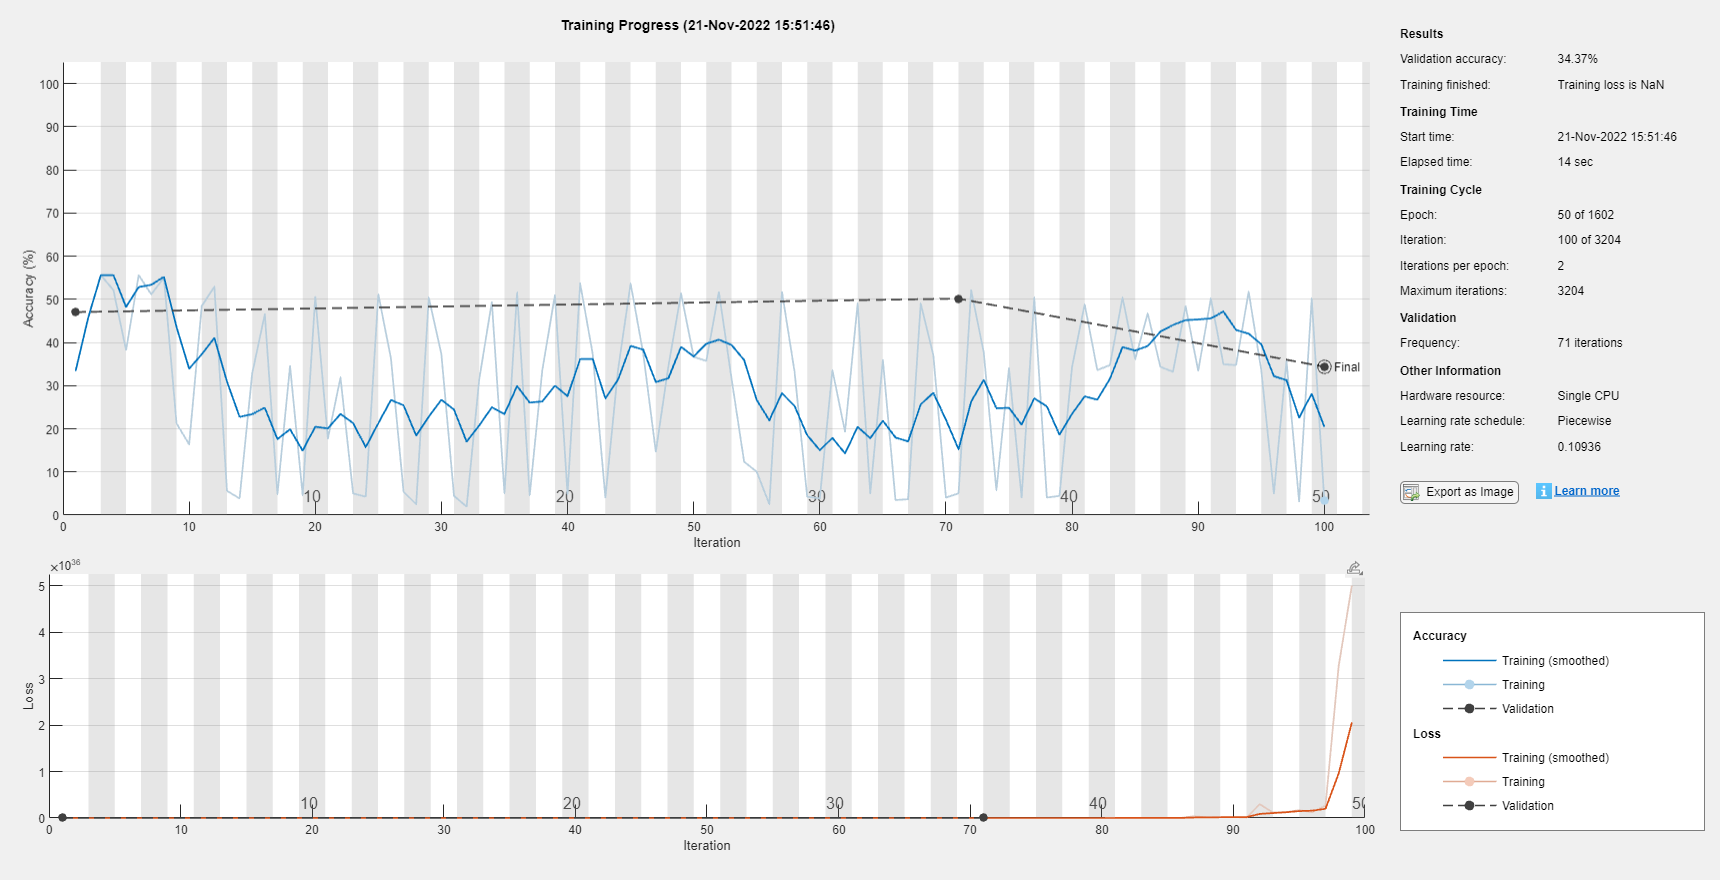

Unrecognized function or variable 'fileName'.

Error in objFcnCNN/valErrorFcn (line 47)
            save(ESPConst.PATH_CNNS + fileName, ...

Error in BayesianOptimization/callObjNormally (line 2559)
                        [Objective, ConstraintViolations, UserData] = this.ObjectiveFcn(conditionalizeX(this, X));

datasets = dir(ESPConst.PATH_DATASET_PREPROCESSED + "*" + ESPConst.EXTENSION_DATA);
for i=1:length(datasets)
    n = datasets(i).name;
    if ~ contains(n, "-" + ESPConst.BALANCE_MODE_LARGEST_SUM)
        continue;
    end
    path = ESPConst.PATH_DATASET_PREPROCESSED + n;
    fprintf("Training CNN for " + n + "...");
    t = load(path).data;
    bayesOptimizationCNN(t, t, n);
end

datasets = dir(ESPConst.PATH_DATASET_PREPROCESSED + "*" + ESPConst.EXTENSION_DATA);
for i=1:length(datasets)
   n = datasets(i).name;
    if ~ contains(n, "-" + ESPConst.BALANCE_MODE_LARGEST_SUM)
        continue;
    end
   fprintf("Training LRN for " + n + "...");
   path = ESPConst.PATH_DATASET_PREPROCESSED + n;
   [t, ~] = prepareInput(path, ESPConst.RATIO_TRAIN, ESPConst.RATIO_VAL);
   bayesOptimizationLRN(t, n);
end

aes = dir(ESPConst.PATH_AES + "*" + ESPConst.EXTENSION_DATA);
for i=1:length(aes)
    clusterByAEFeatures(aes(i).name, ESPConst.N_OUTPUT_CLASSES_ALL);
end